# Registering Brain Scans Using Control Points

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

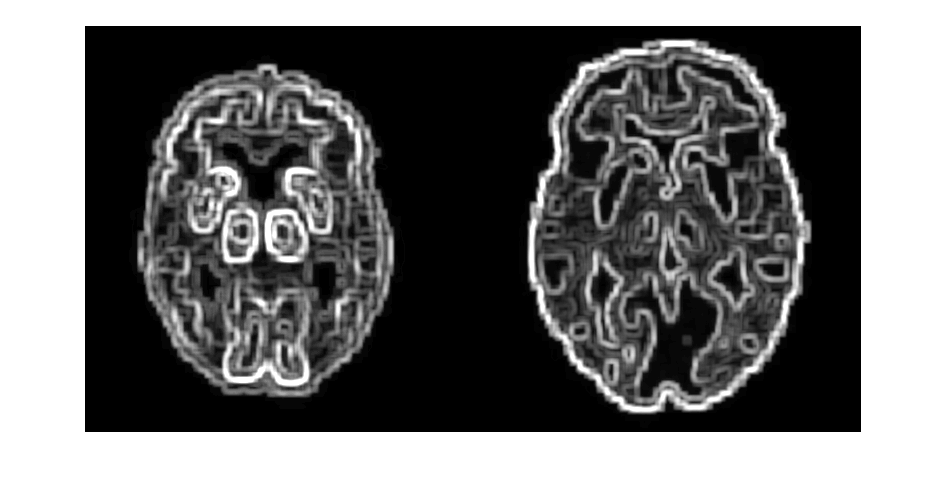

alzheimer = imread("./images/alzheimerBrain.png");
normal = imread("./images/normalBrain.png");
imshowpair(alzheimer, normal, "montage")


alzheimerPts = readmatrix("./images/brainControlPoints.xlsx", Sheet="alzheimerPts")

alzheimerPts =   155.3750  357.3750
  207.6250  360.8750
   71.3750  134.6250
  293.9250  121.5750


normalPts = readmatrix("./images/brainControlPoints.xlsx", Sheet="normalPts")

normalPts =   173.3750  377.3750
  223.1250  375.3750
   81.8750  126.1250
  311.6250   87.3750


## Task 1

In this practice, you will map an image of a brain with Alzheimer's (the moving image) onto an image of a normal brain (the fixed image). Control points identifying locations in the brain with Alzheimer's with locations in the normal brain have been loaded into the workspace as the variables `alzheimerPts` and `normalPts`.

Before calculating the geometric transformation from the control points, you can fine-tune the control points using cross-correlation. Cross-correlation helps ensure that the control points were placed most accurately.

`movPtsCor` `=` `cpcorr``(``movPts``,``fixPts``,``movIm``,``fixIm``)``;`

The `cpcorr` function adjusts the control points by up to four pixels, so the adjustment may be subtle.

alzheimerPts = cpcorr(alzheimerPts, normalPts, alzheimer, normal)

alzheimerPts =   155.3750  357.3750
  207.6250  360.8750
   71.3750  134.6250
  294.9250  122.5750


## Task 2

You can create a geometric transformation using control points with the `fitgeotrans` function.

`tForm` `=` `fitgeotrans``(``movingPts``,``fixedPts``,``type``)`

tForm = fitgeotrans(alzheimerPts, normalPts, "affine");

## Task 3

Rfixed = imref2d(size(normal))

Rfixed =   imref2d with properties:

           XWorldLimits: [0.5000 388.5000]
           YWorldLimits: [0.5000 402.5000]
              ImageSize: [402 388]
    PixelExtentInWorldX: 1
    PixelExtentInWorldY: 1
    ImageExtentInWorldX: 388
    ImageExtentInWorldY: 402
       XIntrinsicLimits: [0.5000 388.5000]
       YIntrinsicLimits: [0.5000 402.5000]


## Task 4

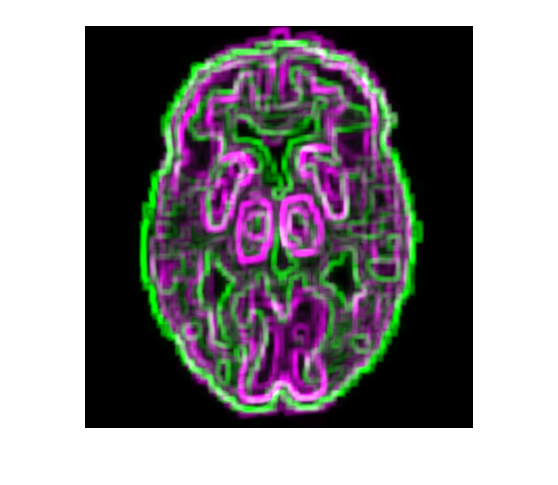

alzTransform = imwarp(alzheimer, tForm, "OutputView", Rfixed);
imshowpair(normal, alzTransform)